## Utilizziamo anche le features

## Flag di configurazione

Variabili che permettono l'esecuzione selettiva del codice e scelta di alcuni parametri come la rete da utilizzare.

% === VARIABILI DI STAMPA ================== %
printTrainingSet = 0;
printTestSet = 0;
printConfMatr = 0;

## Caricamento dei dati

Vengono caricati i dati di training, validation e test set come image datastore. imageDatastore automaticamente applica le label alle classi in base ai nomi delle cartelle delle immagini e salva i dati come oggetti ImageDatastore.

% caricamento dei dati
imdsTrain = imageDatastore('dataset/TrainSet/','IncludeSubfolders',true,'LabelSource','foldernames');
imdsValidation = imageDatastore('dataset/ValSet','IncludeSubfolders',true,'LabelSource','foldernames');
imdsTest = imageDatastore('dataset/TestSet/','IncludeSubfolders',true,'LabelSource','foldernames');
%numero di dati caricati
numTrainImages = numel(imdsTrain.Labels)

numTrainImages = 162770

numValImages = numel(imdsValidation.Labels)

numValImages = 19867

numTestImages = numel(imdsTest.Labels)

numTestImages = 19962

## Analisi dei dati

Stampa casuale di alcune delle immagini appartenenti al training set

if printTrainingSet == 1
    idx = randperm(numTrainImages,16);
    figure
    for i = 1:16
        subplot(4,4,i)
        I = readimage(imdsTrain,idx(i));
        imshow(I)
    end
end



F = readmatrix('dataset/TrainSet_features.txt', 'Delimiter', ' ');

%img
X1Train = readall(imdsTrain);
X1Train = cat(4,X1Train{:});
%labels
TTrain = imdsTrain.Labels;
%features
X2Train = F;


dsX1Train = arrayDatastore(X1Train,IterationDimension=4);
dsX2Train = arrayDatastore(X2Train);
dsTTrain = arrayDatastore(TTrain);
dsTrain = combine(dsX1Train,dsX2Train,dsTTrain);

[h, w, numChannels, numObservations] = size(X1Train)

h = 218

w = 178

numChannels = 3

numObservations = 162770

numFeatures = 39;
numClasses = numel(categories(TTrain));

imageInputSize = [h w numChannels];
filterSize = 40;
numFilters = 130;

layers = [
    imageInputLayer(imageInputSize,Normalization="none")
    convolution2dLayer(filterSize,numFilters)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(50)
    flattenLayer
    concatenationLayer(1,2,Name="cat")
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

lgraph = layerGraph(layers);

## Nuovo input

featInput = featureInputLayer(numFeatures,Name="features");
lgraph = addLayers(lgraph,featInput);
lgraph = connectLayers(lgraph,"features","cat/in2");

## Visual network

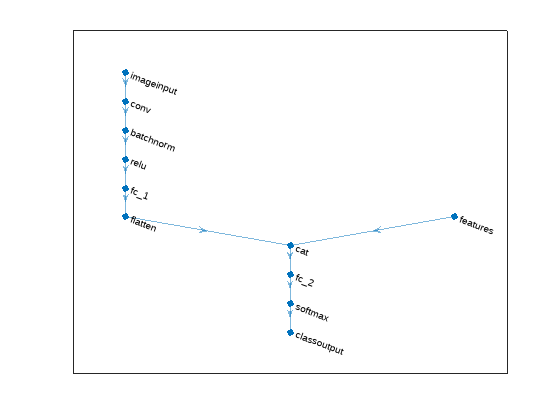

figure
plot(lgraph)

## Training Options

options = trainingOptions("sgdm", ...
    MaxEpochs=15, ...
    InitialLearnRate=0.01, ...
    Plots="training-progress", ...
    Verbose=0, ...
    ExecutionEnvironment="gpu");

net = trainNetwork(dsTrain,lgraph,options);

Error using trainNetwork
Input datastore returned more than one observation per row for network input 2.

## Test network

dsX1Test = arrayDatastore(X1Test,IterationDimension=4);
dsX2Test = arrayDatastore(X2Test);
dsTest = combine(dsX1Test,dsX2Test);

YTest = classify(net,dsTest);

figure
confusionchart(TTest,YTest)

accuracy = mean(YTest == TTest)

idx = randperm(size(X1Test,4),9);
figure
tiledlayout(3,3)
for i = 1:9
    nexttile
    I = X1Test(:,:,:,idx(i));
    imshow(I)

    label = string(YTest(idx(i)));
    title("Predicted Label: " + label)
end